# **Estimate the wall boundary layer distance based on known y+ value**

## **Background**

### **Wall boudary layer's property**

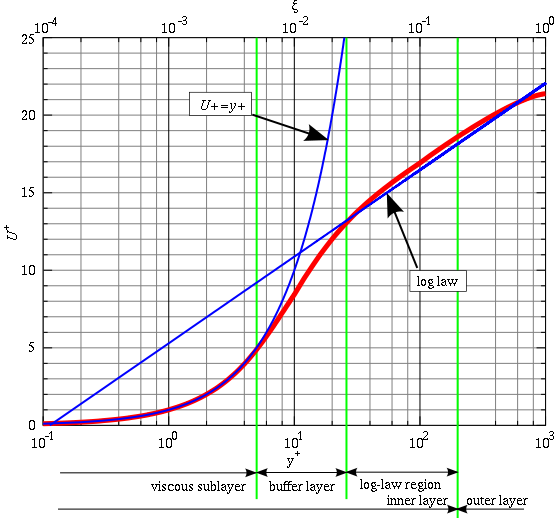

**The viscous sublayer ( y+ < 5):** In the viscous layer, the fluid is dominated by the viscous effect, so it can be assumed that the Reynolds shear stress is negligible. The “linear velocity law” is given by:


$$u^+=y^+$$


**The Buffer layer (5 < y+ < 30):** The buffer layer is the transition region between the viscosity-dominated region and turbulence-dominated part of the flow. Viscous and turbulent stresses are of similar magnitude and since it is complex, the velocity profile is not well defined and the original wall functions avoid the first cell center located in this region.

**The logarithmic area ( y+ > 30): **In the logarithmic layer, turbulence stress dominate the flow and velocity profile varies very slowly with a logarithmic function along the distance y. Formula below describes this region with the Karman constant κ of 0.41 and the constant B=5.2.


$$u^+=\frac{1}{\kappa}ln(y^+)+B$$


## Step by step calculating wall distance with a given y+

kinematic_viscosity=dynamic_viscosity/density;

(1) Write down definition of y+ and rearrange for y


$$y^+=\frac {yu_\tau} {\nu} \rightarrow y=\frac {y^+\nu} {u_\tau}$$


y_plus=y*shear_velocity/kinematic_viscosity;
y=y_plus*kinematic_viscosity/shear_velocity;

(2) Compute the Re number

 
$$Re=\frac{\rho U_\infty L}{\mu}$$


Re_number=density*v_free*L_characteristics/dynamic_viscosity

(3)Next, we calculate $u_\tau$


$$u_\tau=\sqrt{\frac{\tau_{\omega}}{\rho}$$


shear_velocity=sqrt(shear_stress/density);

(3) The wall shear stress $\tau_\omega$ can be calculated from the skin friction coefficient $C_f$


$$\tau_\omega=\frac{1}{2}C_f\rho U_\infty^2$$


shear_stress=1/2*C_f*density*(v_free)^2;

(4) Determine the skin friction coefficientc $C_f$ using Schlichting skin-friction correlation

$C_f=[2 log_{10} ({Re})-0.65]^{-2.3} $ For Re number<$10^9$

C_f=(2*log10(Re_number)-0.65)^(-2.3);

(5) Compute the boundary layer wall distance


$$y=\frac {y^+\nu} {u_\tau}$$


y=y_plus*kinematic_viscosity/shear_velocity;